clc; 
clear all

## Controller Design Criteria

M = 0.05;        
Ts = 5;       
Ess = 0.05;

### System Desired Characteristics

zeta = fzero(@(x) M-exp(-pi*x/sqrt(1-x^2)),0.6);
Wn = 4/Ts/zeta;

## Systen Definition

### Pump and Tank System Transfer Function


$$G\left(s\right)=\frac{A}{\tau s+1}$$


tau = 3.1;        
A = 3;        

s = tf('s');
G = A/(tau*s+1)

G =
 
      3
  ---------
  3.1 s + 1
 
Continuous-time transfer function.



### Feedback Gain (Sensor and Signal Conditioning)

H = 0.01*10;

## Controller and Closed Loop TF

Assume the controller of the following form: $C\left(s\right)=\frac{k\left(\tau s+1\right)}{s^2 +a_1 s+a_0 }$

Forward Path: $G_F \left(s\right)=C\left(s\right)G\left(s\right)=\frac{A}{\tau s+1}\ldotp \frac{k\left(\tau s+1\right)}{s^2 +a_1 s+a_0 }=\frac{\textrm{kA}}{s^2 +a_1 s+a_0 }$

Closed Loop TF: $G_c \left(s\right)=\frac{G_F \left(s\right)}{1+G_F \left(s\right)H\left(s\right)}=\frac{\textrm{kA}}{s^2 +a_1 s+\left(H\left(s\right)\textrm{kA}+a_0 \right)}$

### Apply the Design Criteria to Calculate $k$, $a_1$and $a_0$


$$E_{\mathrm{ss}} =\lim_{s\to 0} s\ldotp \frac{1}{s}\left(1-G_c \left(s\right)\right)$$



$$G_c \left(s\right)=\frac{\mathrm{kA}}{s^2 +2\zeta \omega_n \;s+\omega_n^2 }$$


k = (1-Ess)*Wn^2/A;
a1 = 2*zeta*Wn;
a0 = Wn^2-A*H*k;

### Controller

C = k*(tau*s+1)/(s^2+a1*s+a0)

C =
 
    1.233 s + 0.3977
  ---------------------
  s^2 + 1.547 s + 1.137
 
Continuous-time transfer function.



### Forward Path

GF = C*G

GF =
 
                         
          3.699 s + 1.193
                         
  --------------------------------
                                  
  3.1 s^3 + 5.795 s^2 + 5.071 s   
                                  
                           + 1.137
                                  
 
Continuous-time transfer function.



### Continuous

Gc = feedback(GF,H)

Gc =
 
                         
          3.699 s + 1.193
                         
  --------------------------------
                                  
  3.1 s^3 + 5.795 s^2 + 5.441 s   
                                  
                           + 1.256
                                  
 
Continuous-time transfer function.



#### System Characteristics

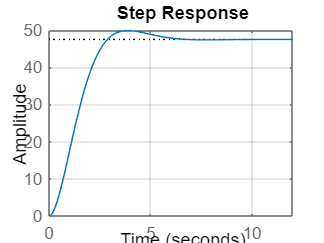

infoC=stepinfo(Gc);        
step(Gc*50);
xlim([0,12])
hold on; grid on; box on;

## Optimum Sampling Time Computation

T=linspace(tau/10,0.01,10);
Gz = cell(length(T),1);  % Forward path in z-domain 
Gc = cell(length(T),1);   % Closed loop in z-domain
info = cell(length(T),1); % System characteristics
Error = 1e-2;       
Tsampling = 0;

for i=1:length(T)
    Gz{i} = c2d(GF,T(i));
    Gc{i} = feedback(Gz{i},H);
    info{i} = stepinfo(Gc{i});
    if abs(infoC.SettlingTime-info{i}.SettlingTime)/infoC.SettlingTime<Error && abs(infoC.Overshoot-info{i}.Overshoot)/infoC.Overshoot<Error
        Tsampling=T(i);
        M = info{i}.Overshoot;
        Ts = info{i}.SettlingTime;
        break
    end
end

## Conclusion

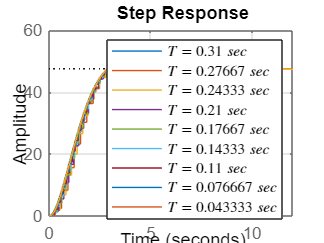

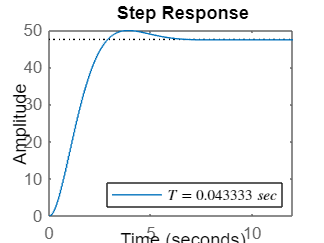

Sampling time =

Tsampling = 0.0433

The continuous controller in s-domain

C =
 
    1.233 s + 0.3977
  ---------------------
  s^2 + 1.547 s + 1.137
 
Continuous-time transfer function.



The continuous controller in z-domain

Cz =
 
   0.05343 z (z-0.9854)
  -----------------------
  (z^2 - 1.933z + 0.9352)
 
Sample time: 0.043333 seconds
Discrete-time zero/pole/gain model.



if Tsampling==0
    disp('The range set for settling time does not meet the error requirement, try smaller settling time');
else
    index = find(T==Tsampling);
    legendList = cell(1,index);
    for i=1:index
    legendList{i}=['$T= ', num2str(T(i)), '\;sec$'];
    step(Gc{i}*50);
    end
    grid on; box on;
    legend(legendList,'interpreter','latex','Location','SouthEast')
    
    figure
    step(Gc{index}*50);
    legend(legendList{index},'interpreter','latex','Location','SouthEast')
    xlim([0,12])

    fprintf('Sampling time =')
    display(Tsampling);

    fprintf('The continuous controller in s-domain')
    display(C);
    fprintf('The continuous controller in z-domain')
    Cz=zpk(c2d(C,Tsampling,'impulse'));
    display(Cz);
end